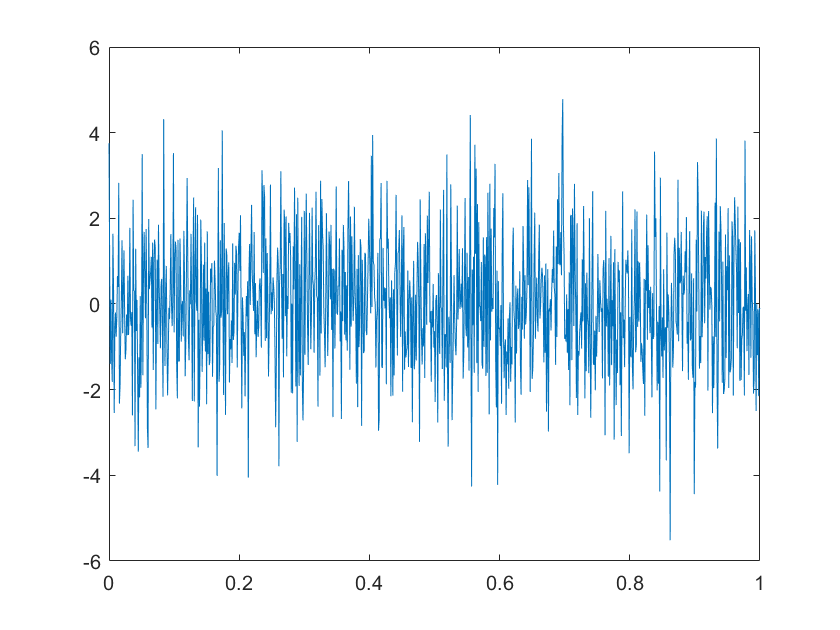


clear all
clc
R = 50.52;
Cap=15e-6;

Fs = 1000;
Ts = 1/Fs;
times = 0:Ts:1;

%t = (0:0.1:10)';
%x = sawtooth(t);




inputSignal = 0.005*sin(2*pi*10000*times) + 0.003*sin(2*pi*5000*times) + 0.0005*sin(2*pi*15000*times) + 0.0002*sin(2*pi*5*times) + 0.001*sin(2*pi*25000*times) + randn(size(times))+randn(size(times));
%%%%plot input
figure
plot(times, inputSignal)


%%%%%%%Bode plote
H_s = tf([1],[7.578e-4 1])

H_s =
 
         1
  ---------------
  0.0007578 s + 1
 
Continuous-time transfer function.



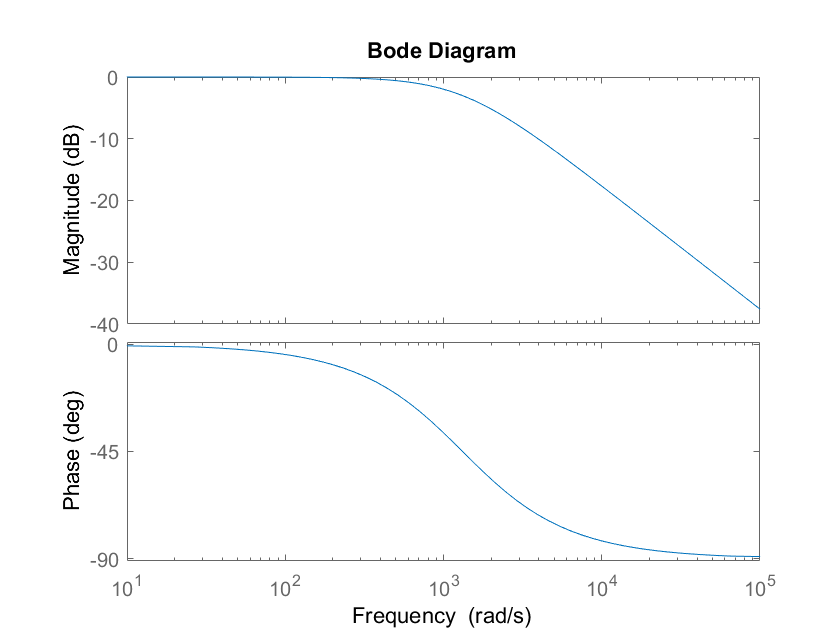

bode(H_s)

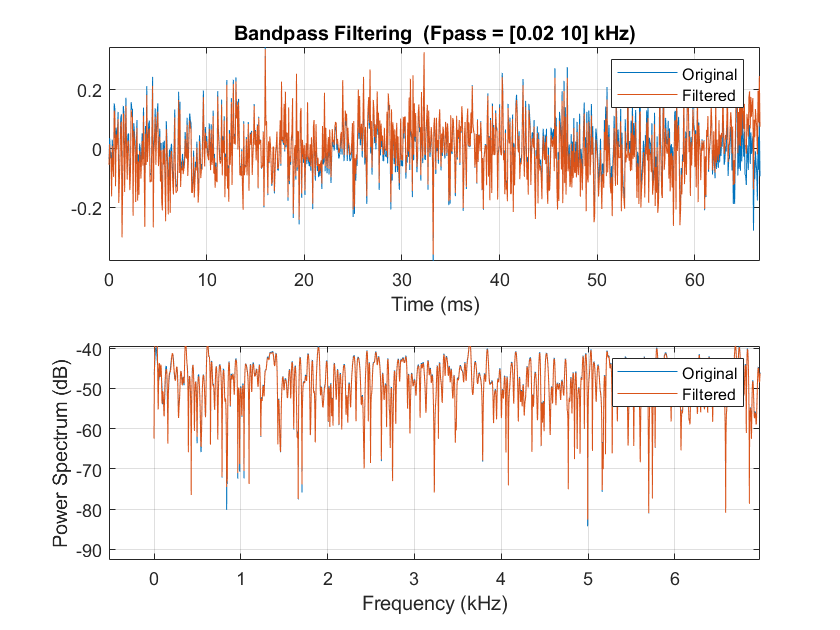


%%%%%%%%%%Low Pass Filter 


%y = awgn(inputSignal,10,'measured');
%plot(t,[inputSignal y])
%legend('Original Signal','Signal with AWGN')


fs = 30e3;
t = 0:Ts:1;
Denominator_=(2*pi*R*Cap);
fc=1/Denominator_; %%%%cut-off frequency
inputSignal_= [0.005 0.003 0.0005 0.0002 0.001]*sin(2*pi*[10000 5000 15000 5 25000]'.*t) + randn(size(t))/10;
%highpass(inputSignal_,20,50000)
%lowpass(inputSignal_,20000,50000)
%bandpass(inputSignal_,[20 20000],50000)

x = [0.005 0.003 0.0005]*sin(2*pi*[10000 5000 15000]'.*t) + randn(size(t))/10;
bandpass(x,[20 10000],15000)